## **Finite Element Method**

clc; 
clear;
syms x f(x) u_e(x)

a=1

a = 1

b = 5

b = 5

c =2*x

$$c = 2\,x$$

f(x) = 4*x^2 - 2*x -4;


%----------------------------------------------------------------------------
deqn = a*diff(u_e,x,2)+b*diff(u_e,x,1)+c*u_e == f;

Value1 = 0;
Value2 = 1;

ic = u_e(0) == Value1;
d_ue(x)= diff(u_e,x);
%ic2 = d_ue(1) == Value2;
ic2=u_e(1) == Value2;

u_exact = dsolve(deqn,[ic ic2]);
exact_sol_f = u_exact;
%----------------------------------------------------------------------------------


P=2 % Only works till P = 6  % guass points restriction 

P = 2

% P Order of Interpolation Function foe element
ndofel=P+1;

% No of elements
e = 10;

% domain of X
x0 = 0;
xn = 1;
% Element length
h = (xn - x0) / e;


PbarKL1 = 2*P -1

PbarKL1 = 3

PbarKL2 = 2*P

PbarKL2 = 4

PbarKL3 = 3*P

PbarKL3 = 6


% max(PbarKL1,PbarKL2,PbarKL3);

Pbar = PbarKL3

Pbar = 6

if mod(Pbar, 2) == 1 % ODD
    nG = (Pbar + 1) / 2;
else % Even
    nG = (Pbar + 2) / 2;
end
nG 

nG = 4


[w,xi] = GaussQuadrature(nG);

 
shapMatrix=zeros(nG,ndofel);
dshapMatrix=zeros(nG,ndofel);

for i = 1:nG
    xi_loc = xi(i);
    [ndofel,shap,dshap] = SHAPE(P,xi_loc);

    for j =1:ndofel
        shapMatrix(i,j)=shap(j);
        dshapMatrix(i,j)=dshap(j);
    end

end
shapMatrix

shapMatrix =    -0.1122    0.8844    0.2278
    0.2278    0.8844   -0.1122
   -0.0598    0.2584    0.8013
    0.8013    0.2584   -0.0598


dshapMatrix

dshapMatrix =    -0.1600   -0.6800    0.8400
   -0.8400    0.6800    0.1600
    0.3611   -1.7223    1.3611
   -1.3611    1.7223   -0.3611




%ndofel=P+1;

% Local stiffness matrix
KL1 = zeros(ndofel, ndofel, 'sym');
KL2 = zeros(ndofel, ndofel, 'sym');
KL3_Ten3 = zeros(ndofel, ndofel,ndofel, 'sym');
F_Mat = zeros(ndofel, ndofel, 'sym');

for i = 1:ndofel
    for j = 1:ndofel
        KL1(i, j) = 0;
        KL2(i, j) = 0;
        F_Mat(i, j) =0;
        for k = 1:nG
            KL1(i, j) = KL1(i, j) + (a * dshapMatrix(k,i) *dshapMatrix(k,j)*(2/h)*w(k));
            KL2(i, j) = KL2(i, j) + (-b * dshapMatrix(k,j) * shapMatrix(k,i)*w(k));
    
            F_Mat(i, j) = F_Mat(i, j) + (-1* shapMatrix(k,i)*shapMatrix(k,j)*(h/2)*w(k));
        end
        
    end
end

for i = 1:ndofel
    for j = 1:ndofel
        for K = 1:ndofel
            KL3_Ten3(i, j,K)= 0;
            for M = 1:nG
                KL3_Ten3(i, j, K) =  KL3_Ten3(i, j, K) + (-1* shapMatrix(M,i)*shapMatrix(M,j)*shapMatrix(M,K)*(h/2)*w(M));
            end
        end

    end
end


KL1_sub = KL1;
KL2_sub = KL2;
KL3_Ten3_sub = KL3_Ten3;
F_Mat_sub = F_Mat;

%generl formula for finding size of gloabl stiffness matrix-(S=OIF*e+1
S=P*e+1;

global_matrix_size = S; % each element has 2 nodal points
% Initialize global stiffness matrix

KL1_global = zeros(global_matrix_size);
KL2_global = zeros(global_matrix_size);
KL3_Ten3_global = zeros(global_matrix_size,global_matrix_size,global_matrix_size);
F_global = zeros(global_matrix_size);

% Loop through each element
for element = 1:ndofel-1:S-1

    % Assemble local stiffness matrix into global stiffness matrix
    start_index = element;
    end_index = element + ndofel-1;
    KL1_global(start_index:end_index, start_index:end_index) = KL1_global(start_index:end_index, start_index:end_index) + KL1_sub;
    KL2_global(start_index:end_index, start_index:end_index) = KL2_global(start_index:end_index, start_index:end_index) + KL2_sub;
    KL3_Ten3_global(start_index:end_index, start_index:end_index,start_index:end_index) = KL3_Ten3_global(start_index:end_index, start_index:end_index,start_index:end_index) + KL3_Ten3_sub;


    F_global(start_index:end_index, start_index:end_index) = F_global(start_index:end_index, start_index:end_index) + F_Mat_sub;
end


X = (x0:h/P:xn)';

c_x = sym(zeros(S, 1));
f_x = sym(zeros(S, 1));

for i = 1:S
    f_x(i) = subs(f, x, X(i));
    c_x(i) = subs(c, x, X(i));
end



% Perform tensor-vector multiplication
KL3_global = zeros(global_matrix_size); % Initialize the result tensor
for i = 1:global_matrix_size

    for j = 1:global_matrix_size

        for k = 1:global_matrix_size

            KL3_global(i, j) = KL3_global(i, j) + KL3_Ten3_global(i, j, k) * c_x(k);
        end
    end
end

%K_global_inverse=InverseTDMA(K_global)

Fv = F_global*f_x;

du_dx = -3;

% Dirichlet Boundary Conditions

K_global_D_bc = KL1_global+KL2_global+KL3_global;
g_x_D_bc = sym(zeros(S, 1));
GNM_D_bc= a*g_x_D_bc*du_dx;
RHS_D_bc = GNM_D_bc+Fv;

% Boundary Conditions1
u0 = Value1;
K_global_D_bc(1,:)= [1,zeros(1, S-1)];  %u0 = 0
RHS_D_bc(1) = u0;  % RHS of equation

% Boundary Conditions2
un = Value2;
K_global_D_bc(end,:)= [zeros(1, S-1), 1];  %un=-1
RHS_D_bc(end) = un;  % RHS of equation

% % for finding inverse I'm using My TDMA inverse function
% K_global_D_bc_inverse=InverseTDMA(K_global_D_bc);

%The Solution of Dirichlet B.C. using FEM is =
u_D_bc = double(K_global_D_bc\RHS_D_bc);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Dirichlet B.C. using FEM is")

The Solution of Dirichlet B.C. using FEM is


myTable = table(X, u_D_bc, 'VariableNames', {'Nodal point', 'u'});
disp(myTable);

    Nodal point       u   
    ___________    _______

          0              0
       0.05        0.39331
        0.1        0.69003
       0.15        0.91195
        0.2         1.0746
       0.25         1.1911
        0.3          1.271
       0.35         1.3223
        0.4         1.3508
       0.45         1.3614
        0.5         1.3579
       0.55         1.3434
        0.6         1.3202
       0.65         1.2903
        0.7         1.2553
       0.75         1.2166
        0.8         1.1752
       0.85         1.1322
        0.9         1.0882
       0.95         1.0439
          1              1



disp("-------------------------------------------------------------")

-------------------------------------------------------------


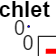

%Plot the FDM Solution and the actual solution
figure;
plot(X, u_D_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [0 1], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;

function [w,xi] = GaussQuadrature(n)
w = zeros(n,1);
xi = zeros(n,1);
    if n==1
        w(1) = 2;
        xi(1) = 0;
    
    elseif n == 2
        w(1) = 1;
        w(2) = 1;
    
        xi(1) = sqrt(3)/3;
        xi(2) = -xi(1);
    elseif n == 3    
        w(1) = 5/9;
        w(2) = 5/9;
        w(3) = 8/9;
    
        xi(1) = sqrt(15)/5;
        xi(2) = -xi(1);
        xi(3) = 0;
    elseif n == 4
        w(1) = 1/2 + (sqrt(30)/36);
        w(2) = 1/2 + (sqrt(30)/36);
        w(3) = 1/2 - (sqrt(30)/36);
        w(4) = 1/2 - (sqrt(30)/36);
    
        xi(1) = sqrt((15-(2*sqrt(30)))/35);
        xi(2) = -xi(1);
        xi(3) = (sqrt(((14*sqrt(30))/5)+21))/7;
        xi(4) = -xi(3);
    elseif n == 5    
        w(1) = 0.236926885056189;
        w(2) = 0.236926885056189;
        w(3) = 0.478628670499366;
        w(4) = 0.478628670499366;
        w(5) = 0.568888888888889;
     
        xi(1) = 0.906179845938664;
        xi(2) = -xi(1);
        xi(3) = 0.538469310105683;
        xi(4) = -xi(3);
        xi(5) = 0;
    elseif n == 6    
        w(1) = 0.171324492379170;
        w(2) = 0.171324492379170;
        w(3) = 0.360761573048139;
        w(4) = 0.360761573048139;
        w(5) = 0.467913934572691;
        w(6) = 0.467913934572691;
     
        xi(1) = 0.932469514203152;
        xi(2) = -xi(1);
        xi(3) = 0.661209386466265;
        xi(4) = -xi(3);
        xi(5) = 0.238619186083197;
        xi(6) = -xi(5);
    elseif n == 7    
        w(1) = 0.129484966168870;
        w(2) = 0.129484966168870;
        w(3) = 0.279705391489277;
        w(4) = 0.279705391489277;
        w(5) = 0.381830050505119;
        w(6) = 0.381830050505119;
        w(7) = 0.417959183673469;
     
        xi(1) = 0.949107912342759;
        xi(2) = -xi(1);
        xi(3) = 0.741531185599394;
        xi(4) = -xi(3);
        xi(5) = 0.405845151377397;
        xi(6) = -xi(5);
        xi(7) = 0;
    elseif n == 8    
        w(1) = 0.101228536290376;
        w(2) = 0.101228536290376;
        w(3) = 0.222381034453374;
        w(4) = 0.222381034453374;
        w(5) = 0.313706645877887;
        w(6) = 0.313706645877887;
        w(7) = 0.362683783378362;
        w(8) = 0.362683783378362;
       
        xi(1) = 0.960289856497536;
        xi(2) = -xi(1);
        xi(3) = 0.796666477413627;
        xi(4) = -xi(3);
        xi(5) = 0.525532409916329;
        xi(6) = -xi(5);
        xi(7) = 0.183434642495650;
        xi(8) = -xi(7);
    elseif n == 9    
        w(1) = 0.081274388361574;
        w(2) = 0.081274388361574;
        w(3) = 0.180648160694857;
        w(4) = 0.180648160694857;
        w(5) = 0.260610696402935;
        w(6) = 0.260610696402935;
        w(7) = 0.312347077040003;
        w(8) = 0.312347077040003;
        w(9) = 0.330239355001260;
       
        xi(1) = 0.968160239507626;
        xi(2) = -xi(1);
        xi(3) = 0.836031107326636;
        xi(4) = -xi(3);
        xi(5) = 0.613371432700590;
        xi(6) = -xi(5);
        xi(7) = 0.324253423403809;
        xi(8) = -xi(7);
        xi(9) = 0;
    elseif n == 10    
        w(1) = 0.066671344308688;
        w(2) = 0.066671344308688;
        w(3) = 0.149451349150581;
        w(4) = 0.149451349150581;
        w(5) = 0.219086362515982;
        w(6) = 0.219086362515982;
        w(7) = 0.269266719309996;
        w(8) = 0.269266719309996;
        w(9) = 0.295524224714753;
        w(10) = 0.295524224714753;
        
        xi(1) = 0.973906528517172;
        xi(2) = -xi(1);
        xi(3) = 0.865063366688985;
        xi(4) = -xi(3);
        xi(5) = 0.679409568299024;
        xi(6) = -xi(5);
        xi(7) = 0.433395394129247;
        xi(8) = -xi(7);
        xi(9) = 0.148874338981631;
        xi(10) = -xi(9);
    end
end

function [ndofel,shap,dshap] = SHAPE(P,xi_loc)

    % Define the polynomial degree P
    
    % Calculate the number of points
    ndofel = P + 1;
    
    syms xi;
    xs = sym('xi', [1 ndofel]);
    
    % Here L is the Numerator differentation of shape function
    L = sym(zeros(ndofel, 1));


            Let P  denote the polynomial degree. 

            Let  ndofel = P+1 denote the number of points.

            The Numerator differentation of shape function

            
$$L_i =\sum_{\begin{array}{c}
j=1\\
j\not= i
\end{array}}^{\textrm{ndofel}} {\left(\prod_{\begin{array}{c}
k=1\\
k\not= i\\
k\not= j
\end{array}}^{\textrm{ndofel}} {\left(x-x_k \right)}\right)}$$


    for i = 1:ndofel
        product = 0; % Initialize the product for the current basis function
        
        % Generate the product terms
        for j = 1:ndofel
            if j ~= i
                term = 1; % Initialize the term for the current product term
                
                % Generate the current product term
                for k = 1:ndofel
                    if k ~= i && k ~= j
                        term = term * (xi - xs(k));
                    end
                end
                
                product = product + term;
            end
        end
        
        % Add the current basis function to the Lagrange basis functions vector
        L(i) = product;
    end
    

    shap = sym(zeros(ndofel,1));
    dshap = sym(zeros(ndofel,1));
    
    % Generating Lagrange interpolating polynomial
    for j = 1:ndofel
        % Compute the product term for each j
        product_term = 1;
        deno = 1;
        for k = 1:ndofel
            if k ~= j
                product_term = product_term * (xi - xs(k)) / (xs(j) - xs(k));
                deno = deno * 1 / (xs(j) - xs(k));
            end
        end 
        shap(j)= product_term;
        dshap(j) = deno*L(j);
    end
    
    
    x_Loc = zeros(1,ndofel);
    for i = 1:ndofel
        x_Loc(i) = -1 + (i-1)*(2/P);
    end
    
    shap = subs(shap,xs,x_Loc);
    dshap = subs(dshap,xs,x_Loc);

    x_Loc = zeros(1,ndofel);
    for i = 1:ndofel
        x_Loc(i) = -1 + (i-1)*(2/P);
    end
    
    shap = subs(shap,xs,x_Loc);
    dshap = subs(dshap,xs,x_Loc);

    % substuting xi value and Transforming from column vector to row vector

    shap = double(subs(shap,xi,xi_loc))';
    dshap = double(subs(dshap,xi,xi_loc))';

end

